# Flurine Interface

The flurine interface is an interactive software that takes the user step-by-step through a series of functions, which require an array of data of a single constituent. These functions are:

- An absorption "Multiplotter", which creates a calibration curve and an overlaying spectra; 

- A fluorescence "Multiplotter" based on Emission-Excitation Matrices (EEM), which creates a calibraton curve, contour and mesh diagram of the highest intensity EEM as well as its emission spectrum at the most efficient excitation wavelength  and excitation spectrum at highest emission inetensity yield;

- A pattern recoginition neural network, which uses fluorence EEMs to classify substances. A complementary diagrams of the confusion matrix and cross entropy will also be supplied

These functions automate most of the processes. Therefore, it is crucial that the user prepare all the data -- which should be exported as *txt,* for import. The naming convention for the data is as follows:

*aaa000x*

Where *aaa *is a three character code for the substance; *000 *are the first three significant figures of the substance's concetration and *x *is a character representing the exponent power. E.g., tryptophan at $5.13 \cdot 10^{-4}$$g\;/l$ is written as: *try513u.txt*

Ideally, the user obtained their data from JASCO devices. If this is not the case, please be aware of your datas particularities and adjust the code accodingly (sorry).

## Load Dictionaries

The user will load two dictionaries: **unitPrefix** is a struct variable that should not be changed. It contains the translation of unit prefixes that are extracted from the file's name. The second dictionary is **substanceIndex**, this is a struct variable that contains all the three letter acronyms of each study's substance; the user may change **substanceIndex** to their liking; however, the indicies must all be unique and three characters long.

load dictionaries.mat

## Import Absorption Data:

answer = questdlg('Do you want to create figures for your Spectrophotometric Data?', ...
	'Inquisition', ...
	'Yes','No','Yes');

switch answer
    case 'Yes'
        spectrophotometric = importAbsorption(substanceIndex, unitPrefix);
end

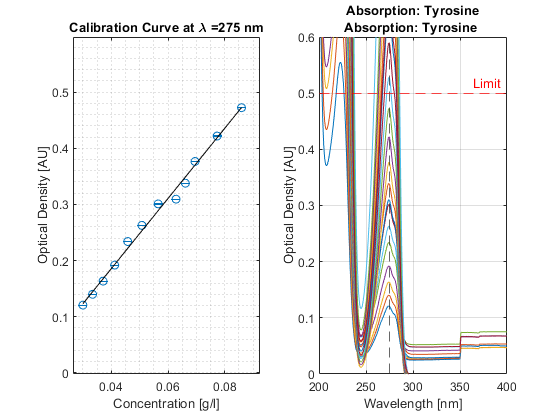

answer = questdlg('Would you like to plot these data?', ...
	'Inquisition', ...
	'Yes','No','Yes');

switch answer
    case 'Yes'
        absorptionPlotter(spectrophotometric);
end